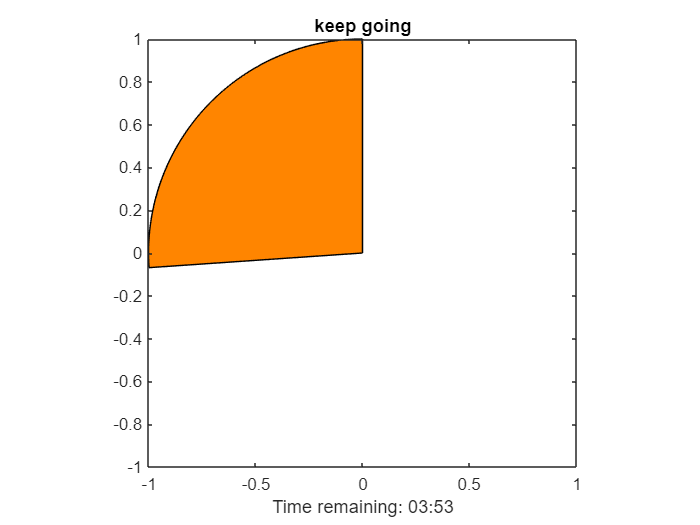

syms M1_0 M2_0 M3_0 M4_0 real
syms EI_1 EI_2 EI_3 EI_4 positive
syms gamma Delta real
syms b F d positive
syms x y real

M1(x) = M1_0 + Delta*x;
M2(x) = M2_0 - Delta*x;
M3(y) = M3_0 - gamma*y;
M4(y) = M4_0 + (gamma-F)*y - F/(2*b)*y^2;

eq1 = M1_0 + M2_0 + gamma*b == F*d;
eq2 = M1_0 + M3_0 == F*d;
eq3 = -Delta*h + M3_0 + M4_0 == F*d;

theta_1 = 1/EI_1 * int(M1(x),x);

theta_2 = 1/EI_2 * int(M2(x),x);
theta_3 = 1/EI_3 * int(M3(x),x);
theta_4 = 1/EI_4 * int(M4(x),x);

delta_1 = int(theta_1(x),x);

Error using sym/subsindex
Invalid indexing or function definition. Indexing must follow MATLAB indexing. Function arguments must be symbolic variables, and function body
must be sym expression.

Error in indexing (line 1075)
            R_tilde = builtin('subsref',L_tilde,Idx);

Related documentation

delta_2 = int(theta_2(x),x);
delta_3 = int(theta_3(x),x);
delta_4 = int(theta_4(x),x);

% 1-3 corner fixed
eq4 = delta_1(0) == 0;
eq5 = delta_3(0) == 0;
eq6 = theta_1(0) == 0;
eq7 = theta_3(0) == 0;

% 3-2 corner connected
eq8 % delta
eq9 % theta

% 2-4 corner connected
eq10 % delta
eq11 % theta

% 4-1 corner connected
eq12 % delta
eq13 % theta

% somehow relate M4 to S4, since I haven't used eq8 in notebook yet

eqs = [eq1 eq2 eq3 eq4 eq5 eq6 eq7 eq8 eq9 eq10 ...
    eq11 eq12 eq13];

% 14 unknowns
unknowns = [8 constants of integration, M1_0 M2_0 M3_0 M4_0, gamma Delta]

% slope deflection method instead
syms F b h positive
syms const real

syms EI [1 4] positive % beams 1,2,3,4
syms L [1 4] positive  % beams 1,2,3,4

syms M [4 4] real      % joints A,B,C,D  
M_f = sym(zeros(4));   % joints A,B,C,D
syms theta [4 1] real  % joints A,B,C,D
theta(2) = 0;

syms delta_x delta_y real
delta  = [delta_x delta_x delta_y delta_y];
M_external = [0 -F*b 0 0];

M_f(1,4) = F*b/12;
M_f(4,1) = F*b/12;

syms eqns

% slope deflection equations: double loop through joints
possible_j = 1:4;
for i=1:4
    valid_j_tf = isodd(i-possible_j);
    valid_j = possible_j(valid_j_tf);
    for j=valid_j
        beam = get_beam(i,j);
        % slope deflection equations (8)
        eqn = 4 * EI(beam) / L(beam) * theta(i) ...
                    + 2 * EI(beam) / L(beam) * theta(j) ...
                    - 6 * EI(beam) / L(beam)^2 * delta(beam) ...
                    == M(i,j);
        eqns(end+1) = eqn;
    end
    % joint equilibrium equations (4)
    eqn = sum(M(i,valid_j)) + sum(M_f(i,valid_j)) ...
                    == M_external(i);
    eqns(end+1) = eqn;
end

eqns = eqns(2:end).';
vars = symvar(eqns);
unknowns = vars(ismember(vars,[M(:);delta.';theta]));

% extra eqn (can't figure it out without this)
extra_eqn = delta_x/delta_y == const;

sol = solve([eqns;extra_eqn],unknowns);
sol_cell = struct2cell(sol);
M_solution = simplify(cell2sym(sol_cell(ismember(unknowns,M(:)))));
M_ans = unknowns(ismember(unknowns,M(:)));

M_ans.' == M_solution


M4_0 = M_solution(M_ans == M(1,4));
M4_b = M_solution(M_ans == M(4,1));

M3_0 = M_solution(M_ans == M(2,3));
M3_b = M_solution(M_ans == M(3,2));

M2_0 = M_solution(M_ans == M(3,4));
M2_h = M_solution(M_ans == M(4,3));

M1_0 = M_solution(M_ans == M(2,1));
M1_h = M_solution(M_ans == M(1,2));

S4_0 = F-gamma;
S4_b = -gamma;

Delta       = 1/h * simplify((M1_h - M1_0))

Delta_check = 1/h * simplify((M2_0 - M2_h))


shouldbetrue = simplify(Delta == Delta_check)

const_reqd = solve(shouldbetrue,const)


gamma = 1/b * simplify((M3_0 - M3_b))


syms y
M4_y = M4_0 + (gamma_sub-F)*y + F/(2*b)*y^2;


Delta_sub = simplify(subs(Delta,const,const_reqd))

gamma_sub = simplify(subs(gamma,const,const_reqd))


syms EI L positive % assume all 4 same beams
%M4_y_sub = simplify(subs(M4_y,const,const_reqd));
M4_0_sub = simplify(subs(M4_0,{EI1,EI2,EI3,EI4,L1,L2,L3,L4},{EI,EI,EI,EI,L,L,L,L}))

$$M4\_0\_sub = \frac{F\,b\,\left(45\,\mathrm{const}-38\right)}{48\,\left(\mathrm{const}+1\right)}$$

M4_y_sub = simplify(subs(M4_y,{EI1,EI2,EI3,EI4,L1,L2,L3,L4},{EI,EI,EI,EI,L,L,L,L}))

Error using symengine
Division by zero.

Error in sym/subs>mupadsubs (line 168)
G = mupadmex('symobj::fullsubs',F.s,X2,Y2);

Error in sym/subs (line 153)
    G = mupadsubs(F,X,Y);

function tf = isodd(x) % tf is true/false
    num = (x-1)/2;
    tf = num==floor(num); % if num is integer, then x is odd
end
function beam = get_beam(i,j)
    if     (i==1 || i==2) && (j==1 || j==2)
        beam = 1;
    elseif (i==3 || i==4) && (j==3 || j==4)
        beam = 2;
    elseif (i==2 || i==3) && (j==2 || j==3)
        beam = 3;
    elseif (i==1 || i==4) && (j==1 || j==4)
        beam = 4;
    else
        error('invalid beam')
    end
end
function slope_deflection(A,B,beam_number)
    

end